f = @(x) (cos(2.*x))./(exp(x));
a = 0;
b = (5/4)*pi;
err = (0.5)*(10^(-3));
level = 0;
max_level = 4;
result1 = simpson_recur(f, a, b, err, level, max_level);

max level reached: level = 4, result = 0.335554211958, a = 0.000000000000, b = 0.490873852123 
max level reached: level = 4, result = 0.031560293814, a = 0.490873852123, b = 0.981747704247 
level = 3, result = 0.367114505772, a = 0.000000000000, b = 0.981747704247 
error tolerance satisfied: level = 3, result = -0.186991040178, a = 0.981747704247, b = 1.963495408494 
level = 2, result = 0.180123465594, a = 0.000000000000, b = 1.963495408494 
error tolerance satisfied: level = 2, result = 0.027949068543, a = 1.963495408494, b = 3.926990816987 
level = 1, result = 0.208072534137, a = 0.000000000000, b = 3.926990816987 


xvals = linspace(a,b, (2^(max_level-1))+1);
yvals = f(xvals);

T = table(round(xvals', 3, 'significant') , round(yvals', 3, 'significant'), 'VariableNames', {'x', 'f(x)'});
disp(T)

      x        f(x)  
    _____    ________

        0           1
    0.491        0.34
    0.982      -0.143
     1.47      -0.225
     1.96     -0.0993
     2.45      0.0168
     2.95      0.0486
     3.44      0.0268
     3.93    6.03e-18



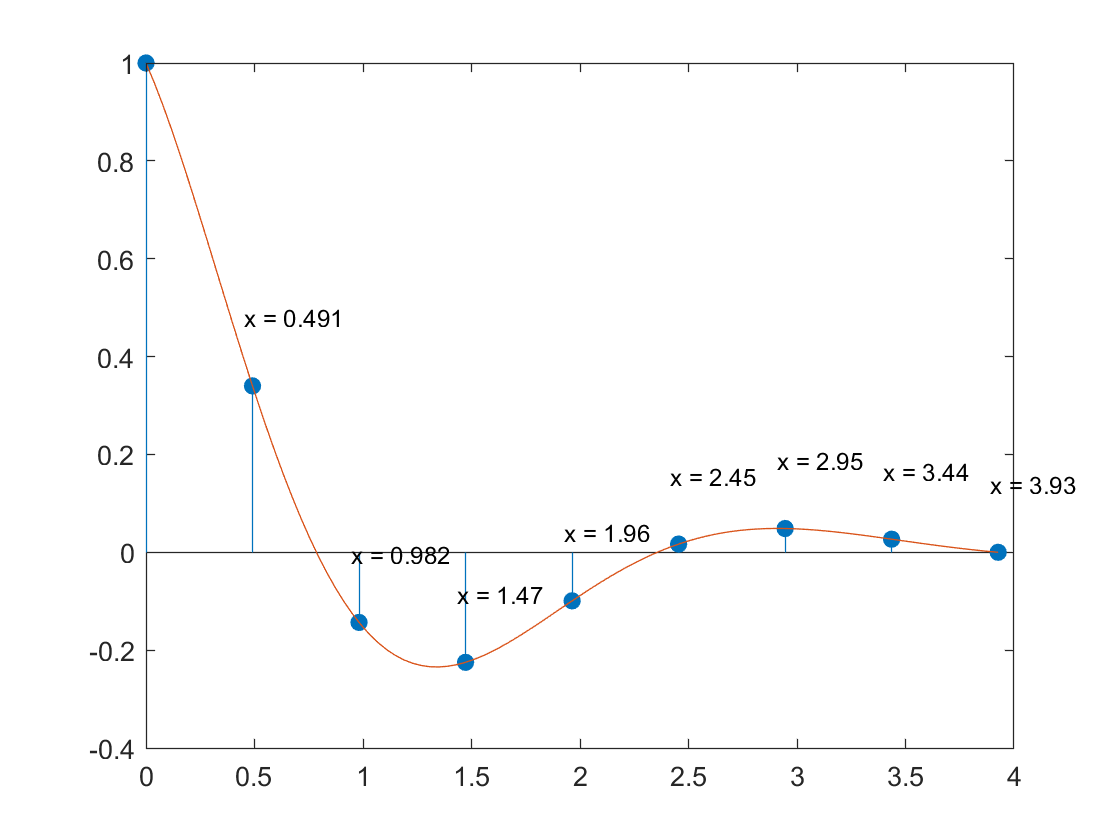

clf
stem(xvals, yvals, 'filled')
xfit = linspace(a,b);
yfit = f(xfit);
hold on
plot(xfit, yfit)

xlim([0 4.00])
ylim([-0.40 1.00])
lbl_dwny = 0.14*max(yvals);
lbl_dwnx = 0.01*max(xvals);
% plot and label the individual points
for i = 2:length(xvals)
     % Label the points with the corresponding 'x' value
     txt = ['x = ', num2str(round(xvals(i), 3, 'significant'))];%, ',', ' ' , ...
         %num2str(round(yvals(i), 2, 'significant')), ')'];
     
     text(xvals(i)-lbl_dwnx,yvals(i)+lbl_dwny,txt, ...
         'FontSize',9);
end
hold off

function result = simpson_recur(f, a, b, err, level, max_level)
    level = level + 1;
    %fprintf('level = %d,  a = %12.12f, b = %12.12f \n', level, a, b)
    h = b - a;
    c = (a + b)/2;
    simpson_1 = (h/6)*(f(a) + 4*f(c) + f(b));
    d = (a + c)/2;
    e = (c + b)/2;
    simpson_2 = (h/12)*(f(a)+ 4*f(d) + 2*f(c) + 4*f(e) + f(b));
    if level >= max_level
        result = simpson_2;
        fprintf('max level reached: level = %d, result = %12.12f, a = %12.12f, b = %12.12f \n', level, result, a, b)
    else
        if abs(simpson_1 - simpson_2) < 15*err
            result = simpson_2 + (simpson_2 - simpson_1)/15;
            fprintf('error tolerance satisfied: level = %d, result = %12.12f, a = %12.12f, b = %12.12f \n', level, result, a, b)
        else
            left_simpson = simpson_recur(f, a, c, err/2, level, max_level);
            right_simpson = simpson_recur(f, c, b, err/2, level, max_level);
            result = left_simpson + right_simpson;
            fprintf('level = %d, result = %12.12f, a = %12.12f, b = %12.12f \n', level, result, a, b)
        end        
    end 
end